% Dane z Simulinka
theta_arm = out.ScopeData.signals(3).values; % kąt ramienia (theta)
r = 10*out.ScopeData.signals(6).values;      % długość ramienia (r), skalowanie do widoczności

mass_size = 0.1; % rozmiar masy na końcu
theta = linspace(pi, 2*pi, 50); % półkole

x_start = 10 * r_start * sin(theta_start);
y_start = 10 * r_start * cos(theta_start);
x_goal  = 10 * r_desired * sin(theta_desired);
y_goal  = 10 * r_desired * cos(theta_desired);

% Inicjalizacja figury
figure;
hold on;
axis equal; grid on;
xlim([-4 4]);
ylim([-0.5 3]);
step=500

step = 500

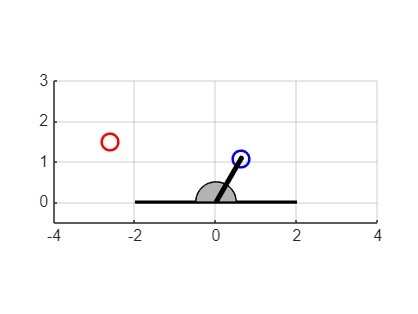

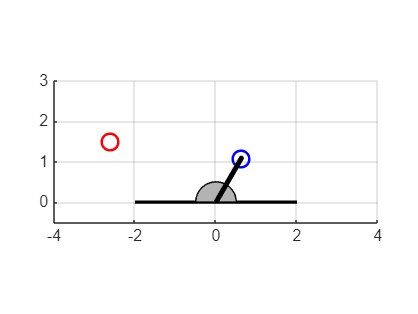


for t = 1:step:length(theta_arm)
    % Czyszczenie klatki
    cla;

    % Nieruchoma podstawa
    plot([-2, 2], [0,0], 'k', 'LineWidth', 2);

    plot(x_start, y_start, 'bo', 'MarkerSize', 10, 'LineWidth', 1.5);

    plot(x_goal, y_goal, 'ro', 'MarkerSize', 10, 'LineWidth', 1.5);

    % Nieruchome półkole
    patch(cos(theta)*0.5, -sin(theta)*0.5, [0.7 0.7 0.7]);

    % Aktualna długość ramienia
    L = r(t);

    % Poprawiona pozycja końca ramienia (kąt 0 oznacza pionowo w górę)
    x_end = L * sin(theta_arm(t));  % sin, bo zero w pionie
    y_end = L * cos(theta_arm(t));  % cos, bo zero w pionie

    % Rysowanie ramienia
    plot([0 x_end], [0 y_end], '-k', 'LineWidth', 3);

    % Rysowanie masy na końcu
    rectangle('Position', [x_end - mass_size/2, y_end - mass_size/2, mass_size, mass_size], ...
              'Curvature', [1,1], 'FaceColor', 'k');

    pause(0.001); % krótka przerwa do płynności animacji
end